clear
xf=[66 67 68 69 70 71 72 73 74 75]';
xm=[60 61 62 63 64 65 66 67 68 69]';
B=[14.1 10.8
    0.41 0.39
    0.43 0.43]

B =    14.1000   10.8000
    0.4100    0.3900
    0.4300    0.4300


Sigma=[2.250 1.125
    1.125 2.250];
k=length(xf);
[Xf,Xm]=meshgrid(xf,xm);
xf=reshape(Xf,k*k,1);
xm=reshape(Xm,k*k,1);
A=chol(Sigma)';
E=(A*randn(2,k*k))';
X=[ones(k*k,1) xf xm]

X =      1    66    60
     1    66    61
     1    66    62
     1    66    63
     1    66    64
     1    66    65
     1    66    66
     1    66    67
     1    66    68
     1    66    69


y=X*B+E

y =    67.7665   65.1255
   64.0017   62.1959
   68.2981   61.7403
   67.5996   63.7499
   74.0476   70.3414
   67.0852   67.4201
   70.6281   65.3821
   71.0421   65.6198
   70.2138   67.6221
   72.9436   69.1078



BB=inv(X'*X)*X'*y

BB =    20.3367   20.2807
    0.3528    0.3019
    0.3946    0.3808



betas=[15 1 1;10 1 1]'

betas =     15    10
     1     1
     1     1



dQa=deltaQ(X,y,betas);

Gamma=0.00001;
beta=betas;
dQ=dQa;

n=0;

Q(1:2,1)=0;
Q(1:2,2)=likelihood(y,X,beta)';


while abs(norm(Q(end)-Q(end-1))) >= 0.05

    dQ=deltaQ(X,y,beta);
    Q=[Q likelihood(y,X,beta)'];
    beta=betaladd1(Gamma,beta,dQ);
    n=n+1;
    if mod(n,10000) ==0
        n
    end
end

beta

beta =    14.9914    9.9915
    0.3963    0.3997
    0.4476    0.4509


yb=X*beta

yb =    68.0006   63.4257
   68.4482   63.8766
   68.8958   64.3275
   69.3434   64.7784
   69.7910   65.2292
   70.2386   65.6801
   70.6862   66.1310
   71.1338   66.5819
   71.5814   67.0327
   72.0290   67.4836


ee=yb-y

ee =     0.2341   -1.6998
    4.4465    1.6807
    0.5977    2.5871
    1.7438    1.0285
   -4.2566   -5.1122
    3.1535   -1.7400
    0.0581    0.7488
    0.0917    0.9621
    1.3676   -0.5893
   -0.9145   -1.6241


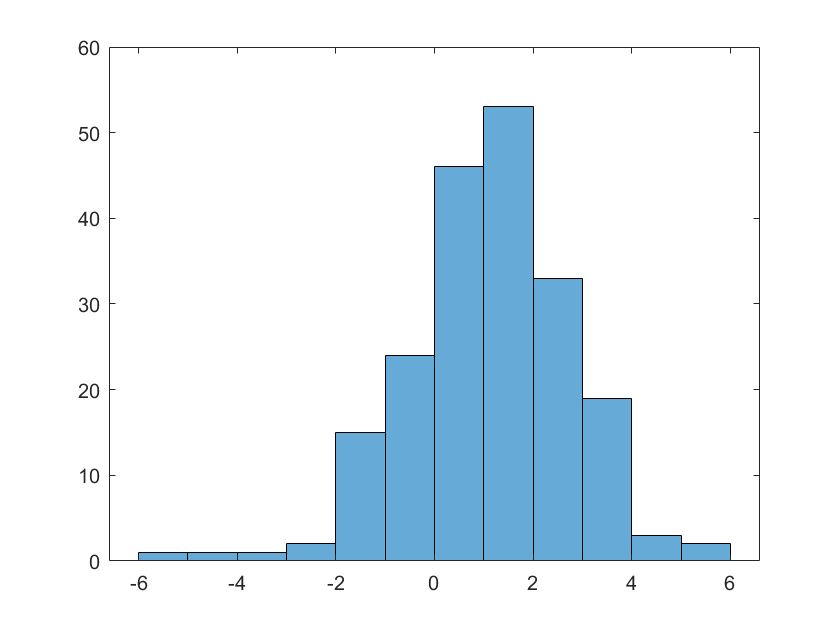

histogram(ee)

function [dQ]=deltaQ(X,y,beta)
    [n,m] = size(X);
    dQ=-2/(n)*(X'*y-X'*X*beta);
end

function [beta1]=betaladd1(Gamma,beta,dQ)
    beta1=beta-Gamma*dQ;
end

function [a]=acti(beta,X)
    a=beta'*X';
end

function [Q]=likelihood(y,X,beta)
    [n,m] = size(y);
    Q=1/n*sum((y-acti(beta,X)').^2,1);
end

function [pQ]=deriQ(y,X,B)
    [k,m] = size(y);
    pQ=-2/k*sum((y-X*B)'*X(1:k,2:3),'all');

end